clear 
close all
rng(5)

%Here we are going to load the created map data.
g = 4;
load("2D\occupancy_map_data"+g+".mat")
map = Map;


load ("2D\occupancy_map"+g+".mat")
Map = occupancyMap(omap);


%Here we are going to set up the start and end parameters, 
%start_orientation and goal_orinetation parameter will determine how the
%algorithm will connect to it, it has to be given in radian
%

start_x = 5;
start_y = 8;
start_orientation = 0;
goal_x = 17;
goal_y = 17;
goal_orientation = 0;

robot_pose = [start_x start_y start_orientation];
goal_pose = [goal_x goal_y goal_orientation];



%Lidar setup
lidar = rangeSensor;
%VFH setup
vfh = controllerVFH;
vfh.UseLidarScan = true;

%It is important that the safety distance has to be greater than the UAV
%speed
vfh.SafetyDistance = 0.5;
%Limits for range readings, specified as a 2-element vector with elements 
% measured in meters. The range readings specified when calling the object
% are considered only if they fall within the distance limits. Use the lower
% distance limit to ignore false positives from poor sensor performance at 
% lower ranges. Use the upper limit to ignore obstacles that are too far 
% from the vehicle.
vfh.DistanceLimits = [0.5 2];

%We show it to see our first part
MapFigure = figure;
VFHFigure = figure;
figure(MapFigure);
show(Map)
Map

Map =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [20 20]
             XLocalLimits: [0 20]
             YLocalLimits: [0 20]
             XWorldLimits: [0 20]
             YWorldLimits: [0 20]


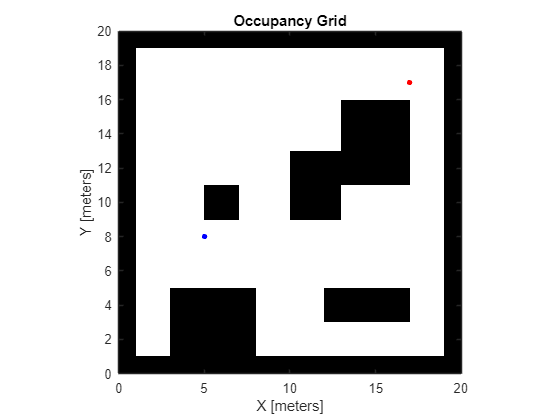

hold on
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color',"red");

trigger = true

trigger = logical
   1


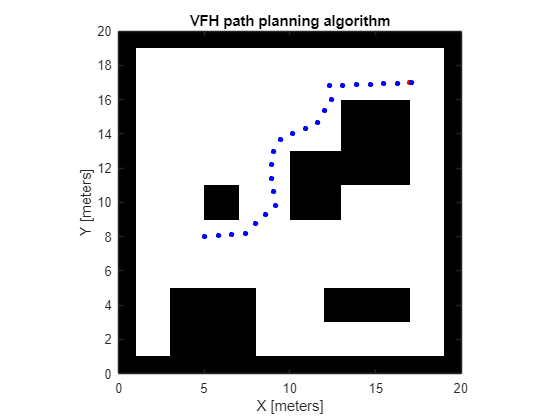

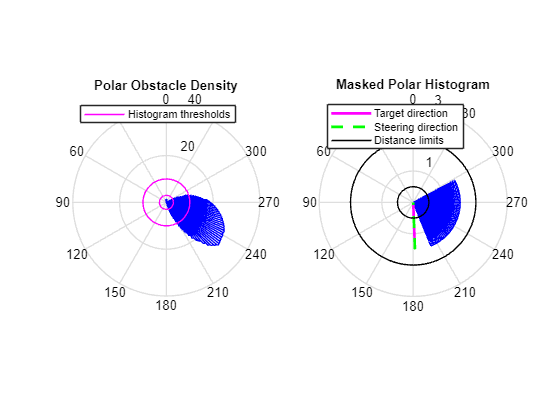

trigger = logical
   0


test = 100;
counter = 1;

%We are going to repeat the process until trigger turns false. Trigger can
%be turned false in two ways. One way is when the algorithm reaches the
%goal. The other is when the algorith maximum number of steps is too many.
%The test variable holds the maximum number of steps that the program can
%make. If the counter variable becomes greater than  the test variable,
%than the trigger will turn false
while trigger
    %Lidar measures
    [ranges,angles] = lidar(robot_pose,Map);


    %Geometry about the angles the be appropriate
    %We calculate the Eucladean distance between the start and end coordinates
    tavolsag_x = goal_pose(1) - robot_pose(1);
    tavolsag_y = goal_pose(2) - robot_pose(2);

    %We use the atan2d to get back the corresponding angle that is in the four
    %quadrant
    goal_angle = atan2d(tavolsag_y,tavolsag_x);
    %We make a correction with the original orientation of the UAV
    goal_angle= deg2rad(goal_angle)+deg2rad(0-start_orientation);
    %We scan the virtual environment
    scan = lidarScan(ranges,angles);
    %We rotate it to be according to the drone orientation
    rotateScan = transformScan(scan,[0,0,robot_pose(3)+deg2rad(0-start_orientation)]);

    %Use the VFH algorithm to calculate the required steering angle in rad
    steeringDir = vfh(rotateScan,goal_angle);
    steeringDir;
    %Convert it to deg
    new_deg = rad2deg(steeringDir);
    figure(VFHFigure)
    show(vfh)
    %Drone parameter setup
    v_drone = 0.2; %m/s [currently be at 0.2, later we can do dynamic adjustments]

    robot_pose(3) = new_deg;
    robot_pose(1) = robot_pose(1)+cosd(new_deg)*v_drone;
    robot_pose(2) = robot_pose(2)+sind(new_deg)*v_drone;
    figure(MapFigure);
    plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
    title("VFH path planning algorithm")
    drawnow
    
    %It stops the algorithm if the UAV is withing the threshold
    if abs(tavolsag_x) < 0.4 && abs(tavolsag_y) < 0.3
        trigger = false
    end

    %It stops the algorithm if it does not find a solution
    if counter > test
        break
    end

    counter = counter+1;
end